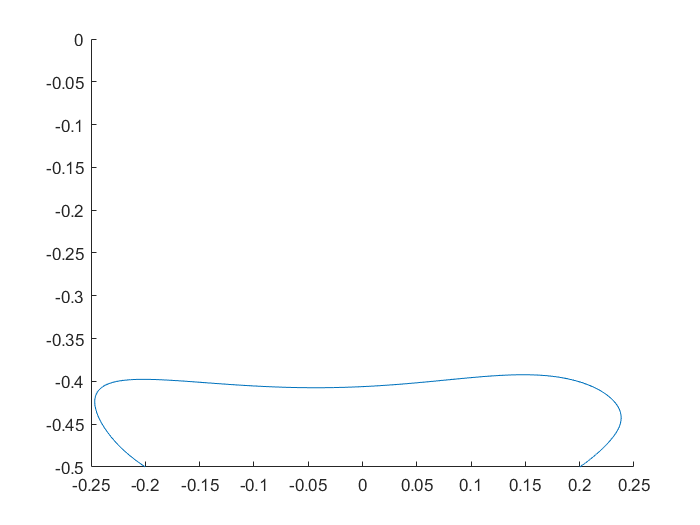

clear; close all; clc;
t = 0:0.01:1;
B = [0 0.8 1 1
     1 1 0.8 0];
c1 = ((1-t).^3)*B(1,1) + 3*((1-t).^2).*t*B(1,2) + 3*(1-t).*(t.^2)*B(1,3) + (t.^3)*B(1,4);
% c2 = ((1-t).^3)*B(1,1) + 3*((1-t).^2).*t*B(1,2) + 3*(1-t).*(t.^2)*B(1,3) + (t.^3)*B(1,4);
Px = [-0.2,-0.259,-0.275,-0.384, 0.261,-0.017, 0.248, 0.267, 0.259, 0.2];
Pz = [-0.5,-0.45,-0.406,-0.065,-1.031,0.095,-0.545,-0.374,-0.45,-0.5];
x = bezier(Px,t);
y = bezier(Pz,t);
figure;
hold on;
% plot(t,c1);
plot(x,y);

% legend("control","function test", 'Location',"best");
% n = length(P);
% B = 0;
% for i = 1:n
%     B(i) = (nchoosek(n-1,i-1).*((1-t).^(n-(i-1))).*t.^(i-1).*P(i));
% end
